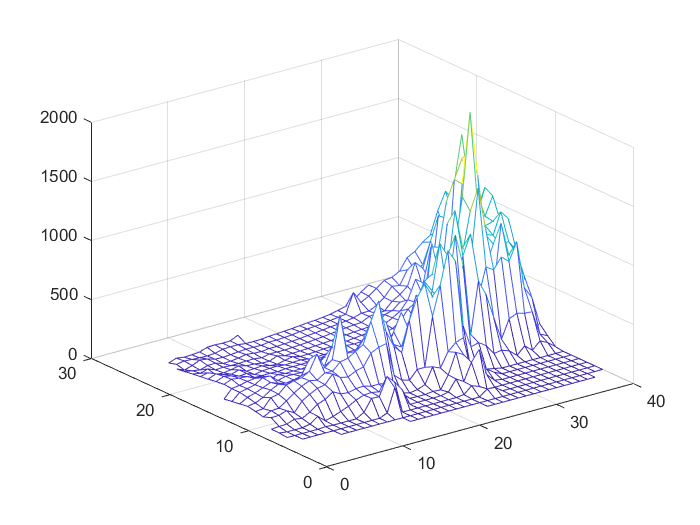

figure(1)
mesh(k)

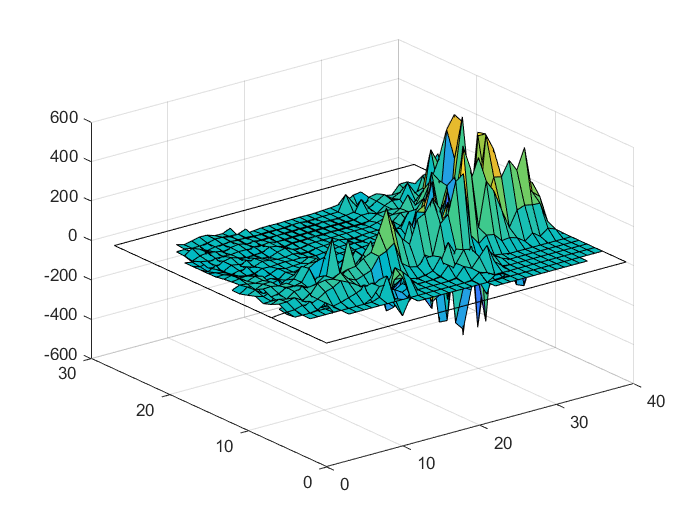


eik = zeros(28, 40);
ejk = zeros(28, 40);
ek = zeros(28, 40);

for i = 2:27
    for j = 2:39
        eik(i, j) = (k(i+1, j) - k(i-1, j)) / 2;
        ejk(i, j) = (k(i, j+1) - k(i, j-1)) / 2;
        ek(i, j) = sqrt(eik(i, j)^2 + ejk(i, j)^2);
    end
end

figure(2)
surf(eik); hold on
surf(ejk)

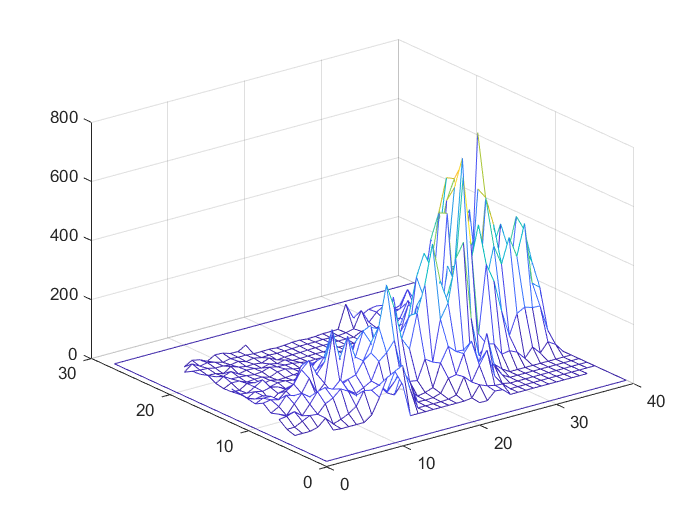


figure(3)
mesh(ek)